# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Specify Forces

f0 = [0; 0.5; 0];     % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];     % Torques on base [nx, ny, nz], in base frame
tau_qm = [0; 0];      % Joint torques

### Launch Simulation

tic
simRes = sim('sim_test');
toc

Elapsed time is 2.833387 seconds.


### Animate Results

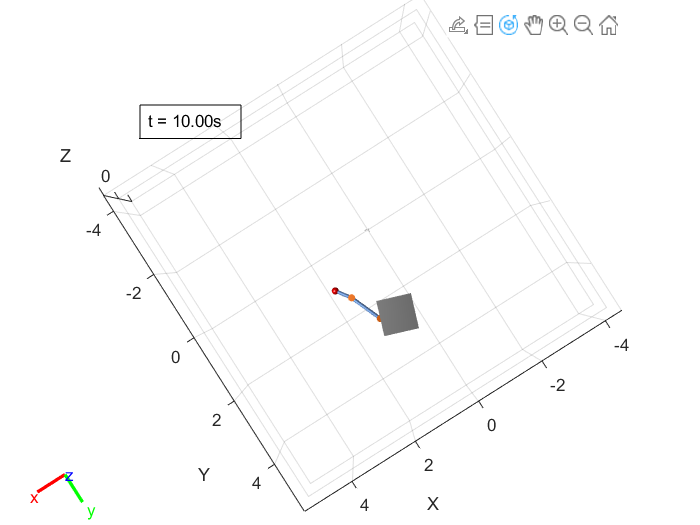

close all
dim = [.2 .5 .3 .3];

framesPerSecond = length(simRes.tout)/simRes.tout(end);
r = rateControl(framesPerSecond);
str = sprintf('t = %.2fs', 0);
h_annot = annotation('textbox', dim,'String', str,'FitBoxToText','on');

for i = 1:length(simRes.q.Time)
    sc.q = simRes.q.Data(:, :, i);
    sc.show('preserve', false, 'fast', true, 'visuals', 'on');
    curT = i/framesPerSecond;
    str = sprintf('t = %.2fs', curT);    
    h_annot.set('String',str);
    drawnow
    waitfor(r);
end

r.DesiredPeriod

ans = 0.1852

r.statistics.AveragePeriod

ans = 0.2088